clc;clear;close all

num = 0.2;
den = [1 0.25 0.2];
m=50;
sys=tf(num,den)

sys =
 
         0.2
  ------------------
  s^2 + 0.25 s + 0.2
 
Continuous-time transfer function.



omegan=sqrt(den(3))

omegan = 0.4472

zeta=den(2)/(2*omegan)

zeta = 0.2795

ts=4/(zeta*omegan)

ts = 32

tp=pi/(omegan*sqrt(1-zeta^2))

tp = 7.3164

pos=exp(-zeta*pi/sqrt(1-zeta^2))*100

pos = 40.0696

t=0:0.1:m;
[yout,t]=step(sys,t);
max_y = max(yout)

max_y = 1.4007

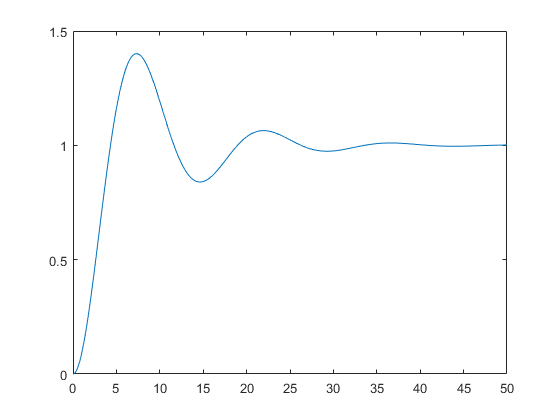

plot(t,yout)

yss = polyval(num,0)/polyval(den,0);
for i=1:m/0.1+1
    if yout(i)<0.9*yss
        t2=t(i);
    else if yout(i) == max_y
        break;
    end
    
end
end
